# Working with Medical Volumes

## Overview

You've seen how to visualize 3D medical images in MATLAB using the Medical Image Labeler App. In this script, you'll learn how to import medical volumes and use an alternative approach to visualize the image quickly. You'll also extract individual slices of data for further analysis.   

3D medical images can be thought of as a stack of 2D images sampled along a third dimension. The stack of images is stored as a 3D array. The elements of the array are often referred to as 3D pixels called voxels. The value at each voxel represents the intensity recorded for that location. 

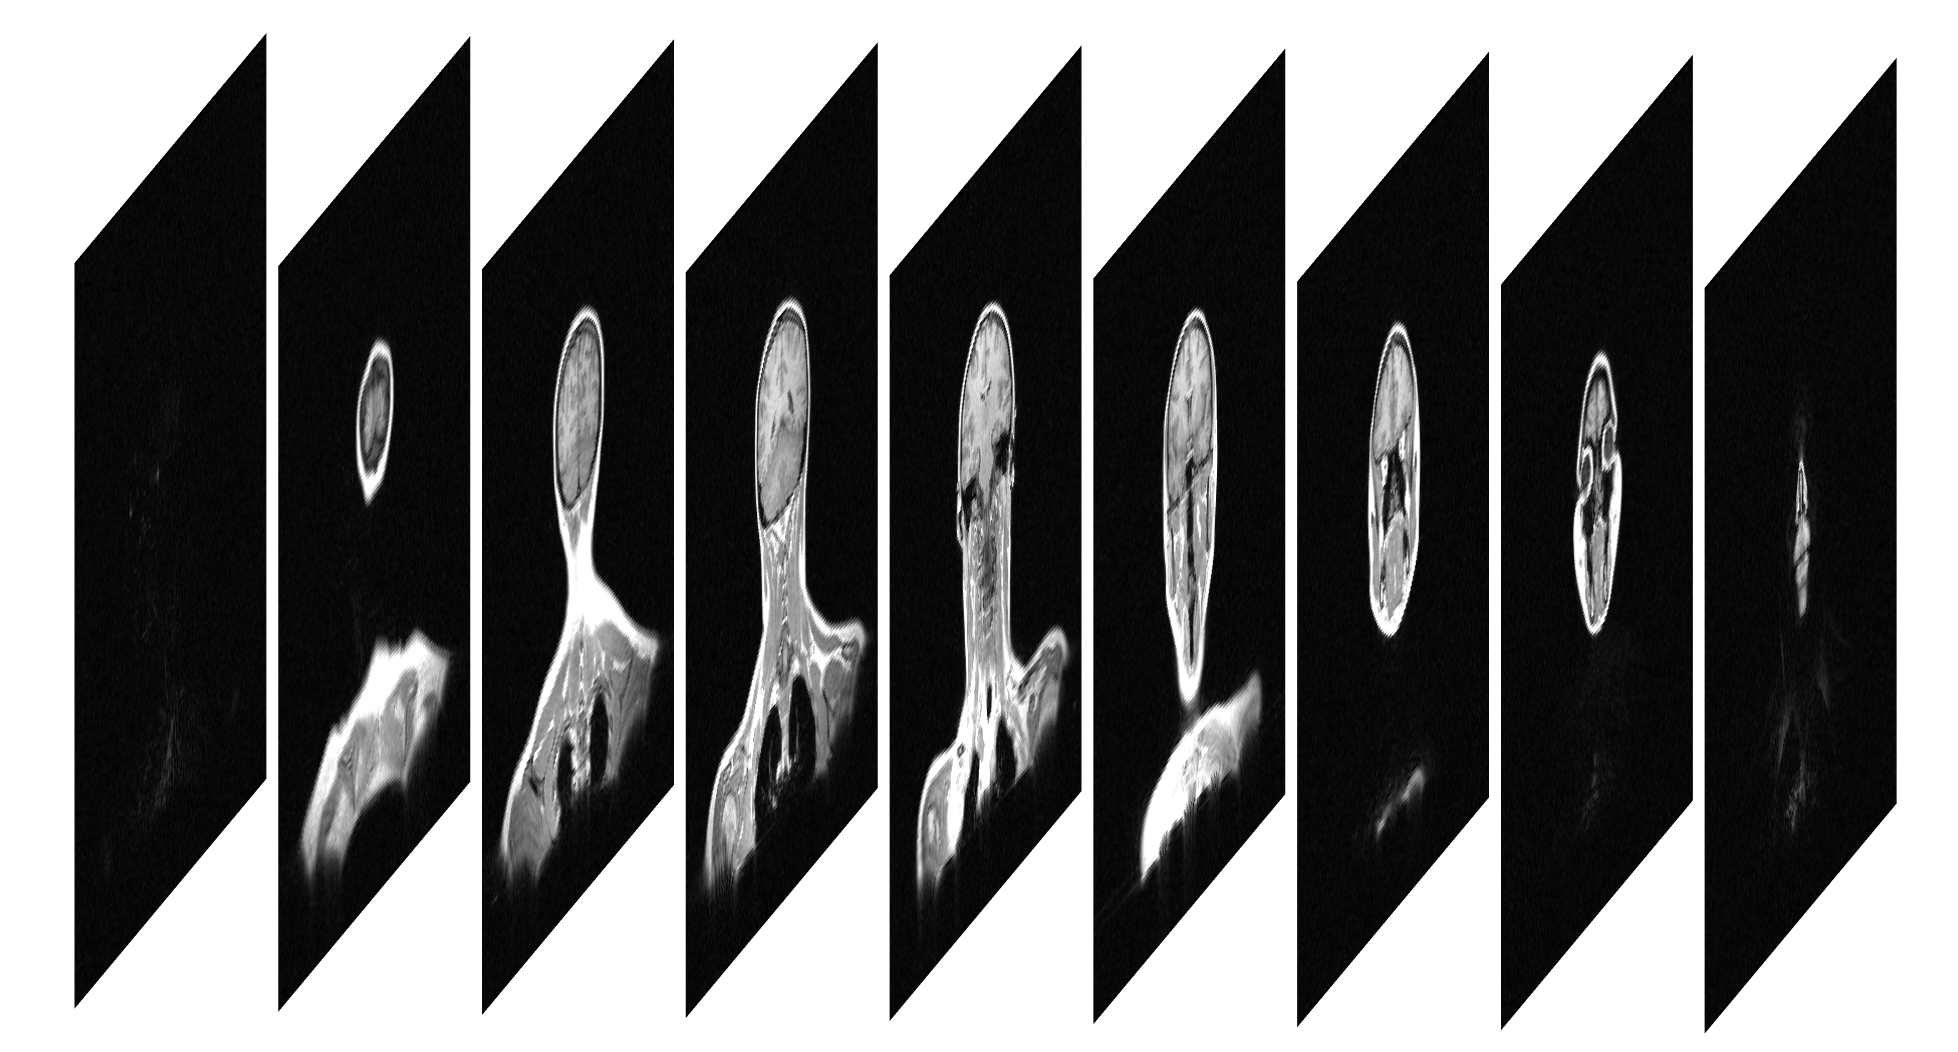

## Import 3D Medical Images

Use the `medicalVolume` function to import a 3D image. When the volume is saved as a directory of images, the input must be the folder containing the volume files.

Use the button below to select one of the MRI folders provided with the course files.

volumeFolder = "";
mri = medicalVolume(volumeFolder)

Similar to a `medicalImage` object, a `medicalVolume` contains the image data along with important meta-data about the image.

- `Voxels` is the 3D array storing the image data

- `VoxelSpacing` and `SpatialUnits` are used to convert voxels to real-world measurements.

- `PlaneMapping` tells you how 3D voxel dimensions are mapped to the patient coordinate system.

- `VolumeGeometry` contains information needed to orient the image to real-world coordinates.

- `Modality` is how the image was acquired, in this case, MR or Magnetic Resonance.

## **View the Data**

Use `orthosliceViewer` to quickly display volumetric image data. A new window for viewing and navigating through the image will open. Meta-data in the `medicalVolume` is used to display the image in the proper orientation and scale.

- Set the `DisplayRange`.property to change the default display limits.

- Manually adjust the window level and window contrast by left-clicking and dragging the mouse on an image.

- Click and drag the crosshairs to move through the slices as you did in the Medical Image Labeler app.

By default, the window level and center from the meta-data are used for the display range, but you can adjust this if needed.

minDisplay = min(mri.Voxels, [], "all");
maxDisplay = max(mri.Voxels, [], "all");
orthosliceViewer(mri, DisplayRange = [minDisplay, maxDisplay]);

## Extract 2D Images

After viewing your volume, you'll likely find several slices of interest that you need to analyze. The `extractSlice` function extracts a 2D image from the volume. Provide the volume, slice number and plane to extract as inputs. The function also returns the real-world position of the top-left pixel of the extracted slice and the spacing between voxels. When spacing in the X and Y directions is not equal, use the spacing information to display the slice with the correct scale 

Use the controls below to extract a slice and view the result. You'll get an error if `sliceNum` exceeds the number of slices in that plane. If that happens, just decrease the value.

plane = "Sagittal";
sliceNum = 60; 
[img, position, spacing] = extractSlice(mri, sliceNum, plane);

% Check if the spacing is equal
spacing
imshow(img, [])

If the spacing in X and Y is not the same, the image may appear distorted. To properly scale the image, specify the real-world image extents in X and Y.

xMax = size(img, 2)*spacing(2);
yMax = size(img, 1)*spacing(1);
imshow(img, [], XData = [0 xMax], YData = [0 yMax])

## Summary

Below is a list of the functions introduced in this reading.

- [`medicalVolume`](https://www.mathworks.com/help/medical-imaging/ref/medicalvolume.html) - Import 3D medical images

- [`orthosliceViewer`](https://www.mathworks.com/help/images/ref/orthosliceviewer.html) - View and explore 3D medical images

- [`extractSlice`](https://www.mathworks.com/help/medical-imaging/ref/medicalvolume.extractslice.html) - Extract a single slice from a medicalVolume oriented in the patient coordinate system.

- [`imshow`](https://www.mathworks.com/help/images/ref/imshow.html) - View extracted slices

*Copyright 2024 The MathWorks, Inc.*